## Classification

Mathilde Marie Duville

**Notice 01:** please, run the codes for figures in the command window to output them with a correct scale for visualization

**Notice 02:** please, run the codes for output variables' creation in the command window to open them from the Workspace for visualization

Here, a Support Vector Machines (SVM) classifier is applied to classify data according to 6 classes (anger, disgust, fear, happinness, neutral, and sadness). 

Please refer to the PowerPoint slide dedicated to it for details about this method (TheoreticalExplanations.pdf).

Initially, 30 features are available to feed the algorithm. A Principal Component Analysis (PCA) can be applied to reduce data dimensionality for optimization by reducing redundancy. Please see the PowerPoint slide dedicated to it for details about this method (TheoreticalExplanations.pdf).

SVM may be optimized by several hyperparameters:

- The **multiclass solution**: SVM are oririginally designed for binary classification. Nevertheless, the multiclass classification problem can be split into multiple binary classifications, following two methods: with **(A) one-vs-all (or one-vs-rest)** a model is created for each class (i.e., here, 6 models would be designed). An artificial class (that could be named "dummy") is created. The dataset is first split into 2 classes, including one of the original classes, and the rest is the dummy class. The algorithm is trained, and the model with the highesy probability of disregarding the dummy class is kept. For instance, here 6 classifiers would be designed: (1) anger vs [disgust, fear, happiness, neutral, sadness], (2) disgust vs [anger, fear, happiness, neutral, sadness], (3) fear vs [anger, disgust, happiness, neutral, sadness], (4) happiness vs [anger, disgust, fear, neutral, sadness], (5) neutral vs [anger, disgust, fear, happiness, sadness], and (6) sadness vs [anger, disgust, fear, happiness, neutral]., **(B) one-vs-one:** a binary classifier is trained on each possible pair of classes. Here, 15 models would be designed: anger vs disgust or fear or happiness or neutral or sadness,  disgust vs fear or happiness or neutral or sadness, fear vs  happiness or neutral or sadness, happiness vs neutral or sadness, neutral vs sadness. To perform classification on a sample,  a majority vote is performed and the class with the most predictions is selected.

- The **kernel**: may be cubic, linear, Gaussian, or quadratic.

- **Scale for the Kernel**: scaling for the data before applying the kernel. Must be a number between 0.001 and 1000, or 'auto'. If is a number, the algorithm divides all elements of the predictor matrix by the value secified. If set to 'auto' the algotithm selects an appropriate scale factor using a heuristic procedure. This heuristic procedure uses subsampling, so estimates can vary from one call to another. see: [https://www.mathworks.com/help/stats/fitrsvm.html#busljl4_sep_shared-KernelScale](https://www.mathworks.com/help/stats/fitrsvm.html#busljl4_sep_shared-KernelScale)

- **The box constraint**: must be a number between 0.001 and 1000. Controls the maximum penalty imposed on  margin-violating observations and helps to prevent overfitting. Fewer support vectors with increasing the box constraint, but increasing computation time. see: [https://www.mathworks.com/help/stats/fitcsvm.html#bt8v_z4-1](https://www.mathworks.com/help/stats/fitcsvm.html#bt8v_z4-1)

Furthermore, cross-validation may be applied, for which the (A) **number of folds** or leave-one-out method must be chosen, (B) the **stratification** for partition must be specified. 

All those hyperparameters must be specified before training the algorithm. In this document, a coding for:

- **running the algorithm with several options of hyperparameters** and store the data in cell. Hyperparameters that leads to the best results (accuracy, Fscore, precision and recall) should be kept.

- running the algorithm with several options of **hyperparameters' optimizations methods** and store the data in cell. Hyperparameters that leads to the best results (accuracy, Fscore, precision and recall) should be kept. **Bayesian optimization, grid, and random search** are available here.

**Confusion matrices, accuracy, precision, recall, and F-scores are outputted.**

A dataset for training and validation is available is the Excel file named "Database_classification_TV". Another one for testing is available is the Excel file "Database_classification_Test".

### **Running the algorithm with several options of hyperparameters**

Read the data 

clc; clear; close all; 
data_ori = readtable('Database_classification_TV.xlsx');

Differences in the scales accross features may lower the accuracy and efficiency of the classifier. Particularly, wide-spread variables (e.g., spread across hundreds or thousand of units, compared to narrow-spread features across decimals or ratio of units) would trigger erroneously high weighted values, resulting in unstable data modelling.

Here, every feature (i.e., columns 2 to 31) is rescaled between 0 and 1 to ensure scale consistency for a more robust posterior classification.

Min-max normalization is used, which, contrary to standardization, does not require the data to be normally distributed. To rescale between 0 and 1, it is defined by: `(sample_column_n-minimum_of_column_n)/(maximum_of_column_n-minimum_of_column_n)`, applied to every feature.

**Minimum and maximum values will be recorded to normalize the testing data afterwards.**

minimum_values = min(table2array(data_ori(:,3:end)));
maximum_values = max(table2array(data_ori(:,3:end))); 

data_rescaled = ((table2array(data_ori(:,3:end)))-(repmat(minimum_values,...
    size(table2array(data_ori(:,3:end)),1), 1))).*repmat((maximum_values-...
    minimum_values).^(-1), size(table2array(data_ori(:,3:end)),1), 1);

data_rescaled = array2table(data_rescaled,...
    'VariableNames',{'Rate','Mean pitch(Hz)','SD pitch',...
    'Jitter local', 'Jitter ppq5','Shimmer local','Shimmer rapq5',...
    'Mean HNR (dB)','Mean intensity (dB)', 'SD intensity',...
    'F1(Hz)','F2 (Hz)','F3(Hz)','B1 in center (Hz)', 'B2 in center(Hz)'...
    'B3 in center(Hz)', 'RMS_Energy', 'Coeff1', 'Coeff2','Coeff3', 'Coeff4'...
    'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8','Coeff9', 'Coeff10', 'Coeff11'...
    'Coeff12', 'Coeff13'});

% Add the classes again
emotions = ["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]; 
emotions = repmat(emotions,(size(data_rescaled,1)/size(emotions,1)),1);    
data_rescaled = [table(emotions, 'VariableNames', {'Emotion'})  data_rescaled]; 

Construct and train the model. The basis of the code is built through the classification learner application (i.e., creation of a function based on model). However, in-hand modifications have been made.

PCA_input = {95}; Multiclass = {'onevsone'}; Kernel = {'cubic'}; % Adjust accordingly

% scalefactor = 0.001:1:1000;
% for i = 1:1:size(scalefactor, 2)
%     KernelScale{1,i} = scalefactor(i);
%     BoxConstraint{1,i} = scalefactor(i);
% end
% KernelScale{1,end+1} = 'auto';

BoxConstraint = {10}; % Adjust accordingly
KernelScale = {'auto'}; % Adjust accordingly

% KFoldsfactor = 2:1:50;
% for i = 1:1:size(KFoldsfactor, 2)
%     KFolds_all{1,i} = KFoldsfactor(i);
% end
% KFolds_all{1,end+1} = 'Leaveout';

KFolds_all = {10, 'Leaveout'}; % Adjust accordingly
Stratify = {1}; % Adjust accordingly

data_rescaled: A table containing predictors and response.

PCA_input: must be 'No' or the percentage of the desired explained variance.

Multiclass: only for data with more than 2 classes: binary SVM to determine pairs of classes (onevsone) or to distinguish every class from the others (onevsall). Must be: 'onevsone' or 'onevsall'.

Kernel: must be 'quadratic', 'linear', 'gaussian' or 'cubic'

KernelScale: scaling for the data before applying the kernel. Must be a number between 0.001 and 1000, or 'auto'. If is a number, the algorithm divides all elements of the predictor matrix by the value secified. If set to 'auto' the algotithm selects an appropriate scale factor using a heuristic procedure. This heuristic procedure uses subsampling, so estimates can vary from one call to another. see: [https://www.mathworks.com/help/stats/fitrsvm.html#busljl4_sep_shared-KernelScale](https://www.mathworks.com/help/stats/fitrsvm.html#busljl4_sep_shared-KernelScale)

BoxConstraint: must be a number between 0.001 and 1000. Controls the maximum penalty imposed on  margin-violating observations and helps to prevent overfitting. Fewer support vectors with increasing the box constraint, but increasing computation time. see: [https://www.mathworks.com/help/stats/fitcsvm.html#bt8v_z4-1](https://www.mathworks.com/help/stats/fitcsvm.html#bt8v_z4-1)

KFolds: number of folds for cross-validation. Must be a number or 'Leaveout' for leave-one-out cross-validation.

Stratify: must be 1 for 'true' or 0 for 'false'. If true each group will contain an equal number of samples per class. If false, a nonstratified random partition is applied during cross-validation

*Output variables of interest: *

trainedClassifier: A struct containing the trained classifier. The struct contains various fields with information about the trained classifier.

trainedClassifier.predictFcn: A function to make predictions on new data. 

accuracy_validation: A double containing the overally accuracy.

recall_validation: A table containing recall values

precision_validation:  A table containing precision values

Fscore_validation:  A table containing Fscore values

**Run the algorithm with several options of hyperparameters and store the data in cell. Hyperparameters that leads to the best results (accuracy, Fscore, precision and recall) should be kept.**

ans = 'PCA option = 95'

ans = 'Multiclass option = onevsone'

ans = 'Kernel option = cubic'

ans = 'KernelScale option = auto'

ans = 'BoxConstraint option = 10'

ans = 'KFolds option = 10'

ans = 'Stratify option = 1'

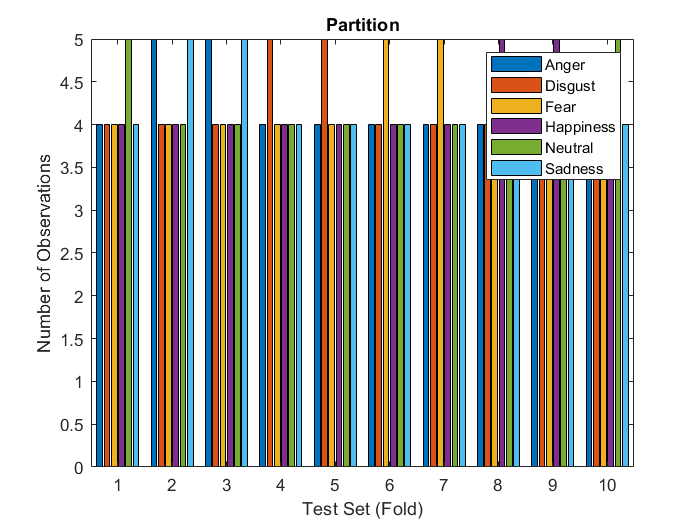

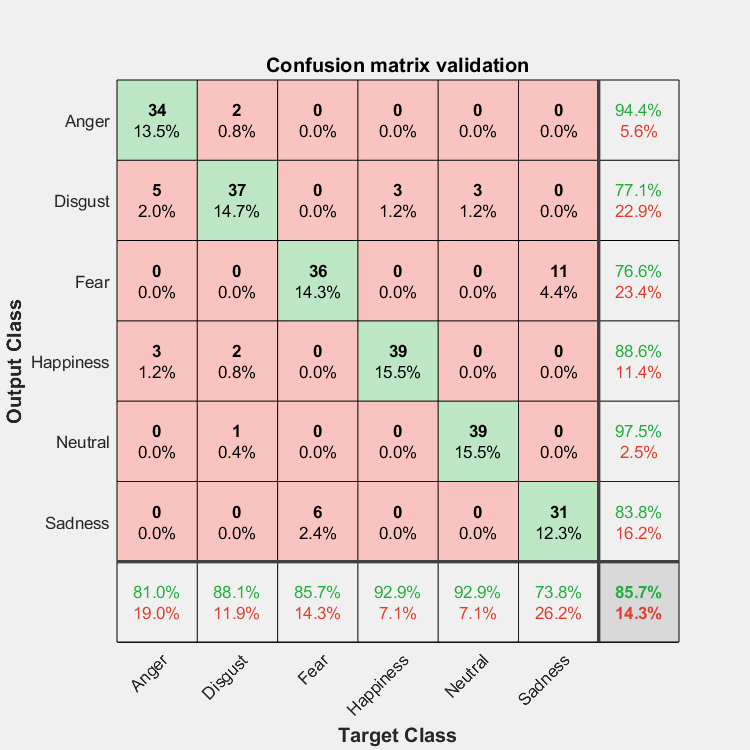

ans = 'KFolds option = Leaveout'

ans = 'Stratify option = 1'

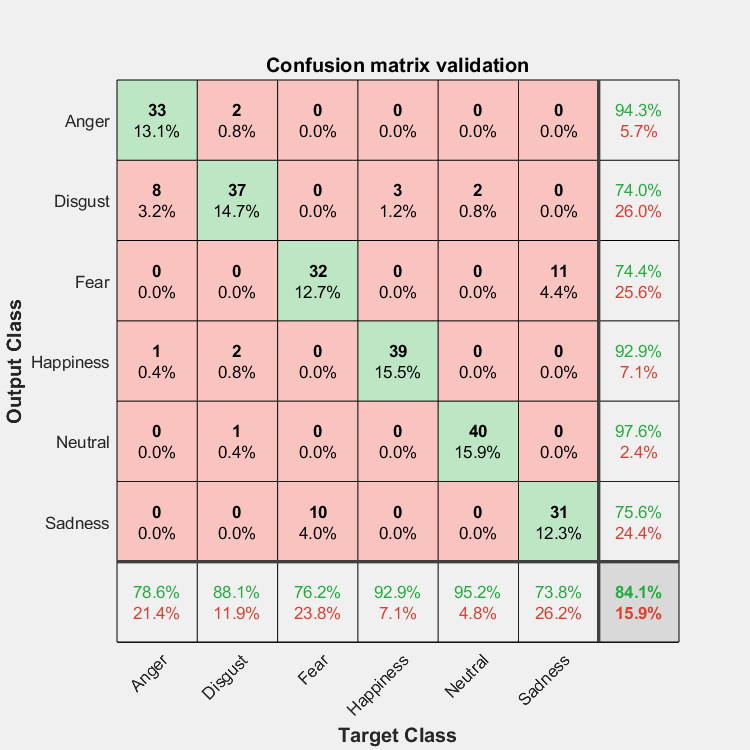

predictorNames = {'Rate', 'Mean pitch(Hz)', 'SD pitch', 'Jitter local', 'Jitter ppq5', 'Shimmer local', 'Shimmer rapq5', 'Mean HNR (dB)', 'Mean intensity (dB)', 'SD intensity', 'F1(Hz)', 'F2 (Hz)', 'F3(Hz)', 'B1 in center (Hz)', 'B2 in center(Hz)', 'B3 in center(Hz)', 'RMS_Energy', 'Coeff1', 'Coeff2', 'Coeff3', 'Coeff4', 'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8', 'Coeff9', 'Coeff10', 'Coeff11', 'Coeff12', 'Coeff13'};
predictors = data_rescaled(:, predictorNames);
response = data_rescaled.Emotion;
% classes_nb = groupsummary(data_rescaled(:,1),"Emotion");
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];
model_structure=[]; 
for PCA_options = 1:1:size(PCA_input,2) %for every value of PCA_input
    ['PCA option = ' num2str(PCA_input{1,PCA_options})]
    for Multiclass_options = 1:1:size(Multiclass,2) %for every value of Multiclass
         ['Multiclass option = ' num2str(Multiclass{1,Multiclass_options})]
          for Kernel_options = 1:1:size(Kernel,2) %for every value of Kernel
              ['Kernel option = ' num2str(Kernel{1,Kernel_options})]
              for KernelScale_options = 1:1:size(KernelScale,2) %for every value of KernelScale
                  ['KernelScale option = ' num2str(KernelScale{1,KernelScale_options})]
                  for BoxConstraint_options = 1:1:size(BoxConstraint,2) %for every value of BoxConstraint
                      ['BoxConstraint option = ' num2str(BoxConstraint{1,BoxConstraint_options})]
                      for KFolds_options = 1:1:size(KFolds_all,2) %for every value of KFolds
                          ['KFolds option = ' num2str(KFolds_all{1,KFolds_options})]
                          for Stratify_options = 1:1:size(Stratify,2) %for every value of Stratify
                              ['Stratify option = ' num2str(Stratify{1,Stratify_options})]

                               % Reminder of the structure for results 
                                model_structure = [];
                                model_structure{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options} = ['PCA option = ' num2str(PCA_input{1,PCA_options})...
                                    ' - Multiclass option = ' num2str(Multiclass{1,Multiclass_options})...
                                    ' - Kernel option = ' num2str(Kernel{1,Kernel_options})...
                                    ' - BoxConstraint option = ' num2str(BoxConstraint{1,BoxConstraint_options})...
                                    ' - KFolds option = ' num2str(KFolds_all{1,KFolds_options})...
                                    ' - Stratify option = ' num2str(Stratify{1,Stratify_options})];
                                
                                if isa(PCA_input{1,PCA_options},'double')
                                    PCA_decision = double(isa(PCA_input{1,PCA_options},'double'));
                                else
                                    PCA_decision = PCA_input{1,PCA_options};
                                end
                                
                                switch PCA_decision
                                    case 1
                                    % Apply a PCA to the predictor matrix.
                                    % Run PCA on numeric predictors only. Categorical predictors are passed through PCA untouched.
                                    isCategoricalPredictorBeforePCA = isCategoricalPredictor;
                                    numericPredictors = predictors(:, ~isCategoricalPredictor);
                                    numericPredictors = table2array(varfun(@double, numericPredictors));
                                    % 'inf' values have to be treated as missing data for PCA.
                                    numericPredictors(isinf(numericPredictors)) = NaN;
                                    [pcaCoefficients, pcaScores, ~, ~, explained, pcaCenters] = pca(...
                                        numericPredictors);
                                    % Keep enough components to explain the desired amount of variance.
                                    explainedVarianceToKeepAsFraction = 95/100;
                                    numComponentsToKeep = find(cumsum(explained)/sum(explained) >= explainedVarianceToKeepAsFraction, 1);
                                    pcaCoefficients = pcaCoefficients(:,1:numComponentsToKeep);
                                    predictors = [array2table(pcaScores(:,1:numComponentsToKeep)), predictors(:, isCategoricalPredictor)];
                                    isCategoricalPredictor = [false(1,numComponentsToKeep), true(1,sum(isCategoricalPredictor))];
                                    
                                    %         Train a classifier
                                    %         This code specifies all the classifier options and trains the classifier.
                                    switch Kernel{1,Kernel_options}
                                        case 'cubic'
                                            template = templateSVM(...
                                                'KernelFunction', 'polynomial', ...
                                                'PolynomialOrder', 3, ...
                                                'KernelScale', KernelScale{1,KernelScale_options}, ...
                                                'BoxConstraint', BoxConstraint{1,BoxConstraint_options}, ...
                                                'Standardize', false);
                                    
                                        case 'gaussian'
                                            template = templateSVM(...
                                                'KernelFunction', 'gaussian', ...
                                                'PolynomialOrder', [], ...
                                                'KernelScale', KernelScale{1,KernelScale_options}, ...
                                                'BoxConstraint', BoxConstraint{1,BoxConstraint_options}{1,BoxConstraint_options}, ...
                                                'Standardize', false);
                                    
                                        case 'quadratic'
                                            template = templateSVM(...
                                                'KernelFunction', 'polynomial', ...
                                                'PolynomialOrder', 2, ...
                                                'KernelScale', KernelScale{1,KernelScale_options}, ...
                                                'BoxConstraint', BoxConstraint{1,BoxConstraint_options}, ...
                                                'Standardize', false);
                                    
                                        case 'linear'
                                            template = templateSVM(...
                                                'KernelFunction', 'linear', ...
                                                'PolynomialOrder', [], ...
                                                'KernelScale', KernelScale{1,KernelScale_options}, ...
                                                'BoxConstraint', BoxConstraint{1,BoxConstraint_options}, ...
                                                'Standardize', false);
                                    end
                                    
                                    classificationSVM = fitcecoc(...
                                        predictors, ...
                                        response, ...
                                        'Learners', template, ...
                                        'Coding', Multiclass{1,Multiclass_options}, ...
                                        'ClassNames', {'Anger'; 'Disgust'; 'Fear'; 'Happiness'; 'Neutral'; 'Sadness'});
                                    
                                    % Create the result struct with predict function
                                    predictorExtractionFcn = @(t) t(:, predictorNames);
                                    pcaTransformationFcn = @(x) [ array2table((table2array(varfun(@double, x(:, ~isCategoricalPredictorBeforePCA))) - pcaCenters) * pcaCoefficients), x(:,isCategoricalPredictorBeforePCA) ];
                                    svmPredictFcn = @(x) predict(classificationSVM, x);
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.predictFcn = @(x) svmPredictFcn(pcaTransformationFcn(predictorExtractionFcn(x)));
                                    
                                    % Add additional fields to the result struct
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.RequiredVariables = {'B1 in center (Hz)', 'B2 in center(Hz)', 'B3 in center(Hz)', 'Coeff1', 'Coeff10', 'Coeff11', 'Coeff12', 'Coeff13', 'Coeff2', 'Coeff3', 'Coeff4', 'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8', 'Coeff9', 'F1(Hz)', 'F2 (Hz)', 'F3(Hz)', 'Jitter local', 'Jitter ppq5', 'Mean HNR (dB)', 'Mean intensity (dB)', 'Mean pitch(Hz)', 'RMS_Energy', 'Rate', 'SD intensity', 'SD pitch', 'Shimmer local', 'Shimmer rapq5'};
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.PCACenters = pcaCenters;
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.PCACoefficients = pcaCoefficients;
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.ClassificationSVM = classificationSVM;
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.About = 'This struct is a trained model exported from Classification Learner R2022a.';
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
                                            
                                    % Extract predictors and response
                                    % This code processes the data into the right shape for training the
                                    % model.
                                    predictorNames = {'Rate', 'Mean pitch(Hz)', 'SD pitch', 'Jitter local', 'Jitter ppq5', 'Shimmer local', 'Shimmer rapq5', 'Mean HNR (dB)', 'Mean intensity (dB)', 'SD intensity', 'F1(Hz)', 'F2 (Hz)', 'F3(Hz)', 'B1 in center (Hz)', 'B2 in center(Hz)', 'B3 in center(Hz)', 'RMS_Energy', 'Coeff1', 'Coeff2', 'Coeff3', 'Coeff4', 'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8', 'Coeff9', 'Coeff10', 'Coeff11', 'Coeff12', 'Coeff13'};
                                    predictors = data_rescaled(:, predictorNames);
                                    response = data_rescaled.Emotion;
                                    % classes_nb = groupsummary(data_rescaled(:,1),"Emotion");
                                    isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];
                                    
                                    % Perform cross-validation
                                    KFolds = KFolds_all{1, KFolds_options};
                                    KFolds_decision = double(isa(KFolds,'double'));
                                    switch KFolds_decision
                                        case 1
                                            cvp = cvpartition(response, "KFold", KFolds, "Stratify",logical(Stratify{1,Stratify_options}));
                                    %                 Plot number of samples in folds
                                            numClasses = size(groupsummary(data_rescaled(:,1),"Emotion"),1);
                                            nTestData = zeros(KFolds,numClasses); figure();
                                            for i = 1:KFolds
                                                testClasses = response(cvp.test(i));
                                                nCounts = countcats(categorical(testClasses));                                                
                                                try nTestData(i,:) = nCounts';                                                    
                                                    bar(nTestData)
                                                    xlabel('Test Set (Fold)'); ylabel('Number of Observations');
                                                    title('Partition'); legend(categories(categorical(response)))
    %                                                     close all
                                                catch
    %                                                     close all
                                                end
                                            end

                                        case 0
                                            cvp = cvpartition(response, "Leaveout");
                                    end
                                    
                                    % Initialize the predictions to the proper sizes
                                    validationPredictions = response;
                                    numObservations = size(predictors, 1);
                                    numClasses = 6;
                                    validationScores = NaN(numObservations, numClasses);
                                    
                                    if isa(KFolds,'double')
                                        KFolds = KFolds;
                                    else
                                        KFolds = numObservations; 
                                    end
                                    
                                    for fold = 1:KFolds
                                        trainingPredictors = predictors(cvp.training(fold), :);
                                        trainingResponse = response(cvp.training(fold), :);
                                        foldIsCategoricalPredictor = isCategoricalPredictor;
                                    
                                        % Apply a PCA to the predictor matrix.
                                        % Run PCA on numeric predictors only. Categorical predictors are passed through PCA untouched.
                                        isCategoricalPredictorBeforePCA = foldIsCategoricalPredictor;
                                        numericPredictors = trainingPredictors(:, ~foldIsCategoricalPredictor);
                                        numericPredictors = table2array(varfun(@double, numericPredictors));
                                        % 'inf' values have to be treated as missing data for PCA.
                                        numericPredictors(isinf(numericPredictors)) = NaN;
                                        [pcaCoefficients, pcaScores, ~, ~, explained, pcaCenters] = pca(...
                                            numericPredictors);
                                        % Keep enough components to explain the desired amount of variance.
                                        explainedVarianceToKeepAsFraction = 95/100;
                                        numComponentsToKeep = find(cumsum(explained)/sum(explained) >= explainedVarianceToKeepAsFraction, 1);
                                        pcaCoefficients = pcaCoefficients(:,1:numComponentsToKeep);
                                        trainingPredictors = [array2table(pcaScores(:,1:numComponentsToKeep)), trainingPredictors(:, foldIsCategoricalPredictor)];
                                        foldIsCategoricalPredictor = [false(1,numComponentsToKeep), true(1,sum(foldIsCategoricalPredictor))];
                                    
                                        % Train a classifier
                                        % This code specifies all the classifier options and trains the classifier.    
                                        classificationSVM = fitcecoc(...
                                            trainingPredictors, ...
                                            trainingResponse, ...
                                            'Learners', template, ...
                                            'Coding', Multiclass{1,Multiclass_options}, ...
                                            'ClassNames', {'Anger'; 'Disgust'; 'Fear'; 'Happiness'; 'Neutral'; 'Sadness'});
                                    
                                        % Create the result struct with predict function
                                        pcaTransformationFcn = @(x) [ array2table((table2array(varfun(@double, x(:, ~isCategoricalPredictorBeforePCA))) - pcaCenters) * pcaCoefficients), x(:,isCategoricalPredictorBeforePCA) ];
                                        svmPredictFcn = @(x) predict(classificationSVM, x);
                                        validationPredictFcn = @(x) svmPredictFcn(pcaTransformationFcn(x));
                                    
                                        % Add additional fields to the result struct        
                                        % Compute validation predictions
                                        validationPredictors = predictors(cvp.test(fold), :);
                                        [foldPredictions, foldScores] = validationPredictFcn(validationPredictors);
                                    
                                        % Store predictions in the original order
                                        validationPredictions(cvp.test(fold), :) = foldPredictions;
                                        validationScores(cvp.test(fold), :) = foldScores;
                                    end
                                    
                                    % Compute validation accuracy
                                    correctPredictions = strcmp(strtrim(validationPredictions), strtrim(response));
                                    isMissing = cellfun(@(x) all(isspace(x)), response, 'UniformOutput', true);
                                    correctPredictions = correctPredictions(~isMissing);
                                    accuracy_validation{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options} = sum(correctPredictions)/length(correctPredictions);
                                    
                                    %  Compute the confusion matrix during validation 
                                    classes = categorical(response);
                                    Order = categorical(["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]);
                                    C2 = confusionmat(classes, categorical(validationPredictions),'Order', Order);
                                    figure();
                                    C4 = plotconfusion(classes, categorical(validationPredictions));
                                    title('Confusion matrix validation')
                                    grid
%                                     close all
                                    %         Compute precision, recall and Fscore during validation
                                    D=diag(C2); L=length(C2); precision_validation =[]; 
                                    for i=1:L
                                       % Number of true positives / (Number of true positives + Number of false positives)
                                       A=C2(:,i); 
                                       precision_validation(i,:) = D(i)/((D(i))+(sum(A(~ismember(1:end, i))))); 
                                       % Number of false=all items column i but the one on the diagonal
                                    end 
                                    recall_validation = [];
                                    for j=1:L
                                        % Number of true positives /(Number of true positives + Number of false negatives)
                                        G = C2(j,:); 
                                        recall_validation(j,:) = D(j)/((D(j))+(sum(G(~ismember(1:end, j)))));  
                                    end
                                    
                                    Fscore_validation = []; Fscore_validation = (2.*precision_validation.*recall_validation)./(precision_validation+recall_validation);
                                    
                                    precision_validation = reshape(precision_validation, 1, []); 
                                    precision_validation_tot{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options} = array2table(precision_validation,'VariableNames',...
                                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                                    
                                    recall_validation = reshape(recall_validation, 1, []); 
                                    recall_validation_tot{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options} = array2table(recall_validation,'VariableNames',...
                                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                                    
                                    Fscore_validation = reshape(Fscore_validation, 1, []); 
                                    Fscore_validation_tot{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options} = array2table(Fscore_validation,'VariableNames',...
                                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                                
                                    case 'No'
                                    % Train a classifier
                                    % This code specifies all the classifier options and trains the classifier.
                                     switch Kernel{1,Kernel_options}
                                        case 'cubic'
                                            template = templateSVM(...
                                                'KernelFunction', 'polynomial', ...
                                                'PolynomialOrder', 3, ...
                                                'KernelScale', KernelScale{1,KernelScale_options}, ...
                                                'BoxConstraint', BoxConstraint{1,BoxConstraint_options}, ...
                                                'Standardize', false);
                                    
                                        case 'gaussian'
                                            template = templateSVM(...
                                                'KernelFunction', 'gaussian', ...
                                                'PolynomialOrder', [], ...
                                                'KernelScale', KernelScale{1,KernelScale_options}, ...
                                                'BoxConstraint', BoxConstraint{1,BoxConstraint_options}, ...
                                                'Standardize', false);
                                    
                                        case 'quadratic'
                                            template = templateSVM(...
                                                'KernelFunction', 'polynomial', ...
                                                'PolynomialOrder', 2, ...
                                                'KernelScale', KernelScale{1,KernelScale_options}, ...
                                                'BoxConstraint', BoxConstraint{1,BoxConstraint_options}, ...
                                                'Standardize', false);
                                    
                                        case 'linear'
                                            template = templateSVM(...
                                                'KernelFunction', 'linear', ...
                                                'PolynomialOrder', [], ...
                                                'KernelScale', KernelScale{1,KernelScale_options}, ...
                                                'BoxConstraint', BoxConstraint{1,BoxConstraint_options}, ...
                                                'Standardize', false);
                                    end
                                    classificationSVM = fitcecoc(...
                                        predictors, ...
                                        response, ...
                                        'Learners', template, ...
                                        'Coding', Multiclass{1,Multiclass_options}, ...
                                        'ClassNames', {'Anger'; 'Disgust'; 'Fear'; 'Happiness'; 'Neutral'; 'Sadness'});
                                    
                                    % Create the result struct with predict function
                                    predictorExtractionFcn = @(t) t(:, predictorNames);
                                    svmPredictFcn = @(x) predict(classificationSVM, x);
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));
                                    
                                    % Add additional fields to the result struct
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.RequiredVariables = {'B1 in center (Hz)', 'B2 in center(Hz)', 'B3 in center(Hz)', 'Coeff1', 'Coeff10', 'Coeff11', 'Coeff12', 'Coeff13', 'Coeff2', 'Coeff3', 'Coeff4', 'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8', 'Coeff9', 'F1(Hz)', 'F2 (Hz)', 'F3(Hz)', 'Jitter local', 'Jitter ppq5', 'Mean HNR (dB)', 'Mean intensity (dB)', 'Mean pitch(Hz)', 'RMS_Energy', 'Rate', 'SD intensity', 'SD pitch', 'Shimmer local', 'Shimmer rapq5'};
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.ClassificationSVM = classificationSVM;
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.About = 'This struct is a trained model exported from Classification Learner R2022a.';
                                    trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
                                    
                                    %         % Perform cross-validation
                                    % 
                                    %         KFolds_decision = double(isa(KFolds,'double'));
                                    %         switch KFolds_decision
                                    %             case 1
                                    % %                 cvp = cvpartition(response, "KFold", KFolds, "Stratify",logical(Stratify));
                                    % % %                 partitionedModel = crossval(trainedClassifier.ClassificationSVM, 'KFold', KFolds);
                                    % %                 partitionedModel = crossval(trainedClassifier.ClassificationSVM,'Partition',cvp);
                                    %             case 0
                                    %                 partitionedModel = crossval(trainedClassifier.ClassificationSVM, 'Leaveout', 'on');
                                    %         end
                                    %         
                                    %         % Compute validation predictions
                                    %         [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
                                    %         
                                    %         % Compute validation accuracy
                                    %         accuracy_validation = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
                                    
                                    % Perform cross-validation
                                    KFolds = KFolds_all{1, KFolds_options};
                                    KFolds_decision = double(isa(KFolds,'double'));
                                    switch KFolds_decision
                                        case 1
                                            cvp = cvpartition(response, "KFold", KFolds, "Stratify",logical(Stratify{1,Stratify_options}));
                                    %                 Plot number of samples in folds
                                            numClasses = size(groupsummary(data_rescaled(:,1),"Emotion"),1);
                                            nTestData = zeros(KFolds,numClasses);
                                            i = []; figure()
                                            for i = 1:KFolds
                                                testClasses = []; testClasses = response(cvp.test(i));
                                                nCounts = []; nCounts = countcats(categorical(testClasses));
                                                try nTestData(i,:) = nCounts';
                                                    bar(nTestData)
                                                    xlabel('Test Set (Fold)'); ylabel('Number of Observations');
                                                    title('Partition'); legend(categories(categorical(response)))
%                                                     close all
                                                catch
%                                                     close all
                                                end
                                            end
                                            
                                            
                                    
                                        case 0
                                            cvp = cvpartition(response, "Leaveout");
                                    end
                                    
                                    % Initialize the predictions to the proper sizes
                                    validationPredictions = response;
                                    numObservations = size(predictors, 1);
                                    numClasses = 6;
                                    validationScores = NaN(numObservations, numClasses);
                                    
                                    if isa(KFolds,'double')
                                        KFolds = KFolds;
                                    else
                                        KFolds = numObservations; 
                                    end
                                    
                                    for fold = 1:KFolds
                                        trainingPredictors = predictors(cvp.training(fold), :);
                                        trainingResponse = response(cvp.training(fold), :);
                                    
                                        % Train a classifier
                                        % This code specifies all the classifier options and trains the classifier.    
                                        classificationSVM = fitcecoc(...
                                            trainingPredictors, ...
                                            trainingResponse, ...
                                            'Learners', template, ...
                                            'Coding', Multiclass{1,Multiclass_options}, ...
                                            'ClassNames', {'Anger'; 'Disgust'; 'Fear'; 'Happiness'; 'Neutral'; 'Sadness'});
                                    
                                        % Create the result struct with predict function
                                        svmPredictFcn = @(x) predict(classificationSVM, x);
                                        validationPredictFcn = @(x) svmPredictFcn(x); 
                                    
                                        % Compute validation predictions
                                        validationPredictors = predictors(cvp.test(fold), :);
                                        [foldPredictions, foldScores] = validationPredictFcn(validationPredictors);
                                    
                                        % Store predictions in the original order
                                        validationPredictions(cvp.test(fold), :) = foldPredictions;
                                        validationScores(cvp.test(fold), :) = foldScores;
                                    end
                                    
                                    % Compute validation accuracy
                                    correctPredictions = strcmp(strtrim(validationPredictions), strtrim(response));
                                    isMissing = cellfun(@(x) all(isspace(x)), response, 'UniformOutput', true);
                                    correctPredictions = correctPredictions(~isMissing);
                                    accuracy_validation{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options} = sum(correctPredictions)/length(correctPredictions);
                                    
                                    %         Compute the confusion matrix during validation 
                                    classes = categorical(response);
                                    Order = categorical(["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]);
                                    C2 = confusionmat(classes, categorical(validationPredictions),'Order', Order);
                                    figure();
                                    C4 = plotconfusion(classes, categorical(validationPredictions));
                                    title('Confusion matrix validation')
                                    grid
%                                     close all
                                    
                                    %         Compute precision, recall and Fscore during validation
                                    D=diag(C2); L=length(C2); precision_validation =[];       
                                    for i=1:L
                                       % Number of true positives / (Number of true positives + Number of false positives)
                                       A=C2(:,i); 
                                       precision_validation(i,:) = D(i)/((D(i))+(sum(A(~ismember(1:end, i))))); 
                                       % Number of false=all items column i but the one on the diagonal
                                    end 
                                    recall_validation = []; 
                                    for j=1:L
                                        % Number of true positives /(Number of true positives + Number of false negatives)
                                        G = C2(j,:); 
                                        recall_validation(j,:) = D(j)/((D(j))+(sum(G(~ismember(1:end, j)))));  
                                    end
                                    
                                    Fscore_validation = []; Fscore_validation = (2.*precision_validation.*recall_validation)./(precision_validation+recall_validation);
                                    
                                    precision_validation = reshape(precision_validation, 1, []); 
                                    precision_validation_tot{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options} = array2table(precision_validation,'VariableNames',...
                                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                                    
                                    recall_validation = reshape(recall_validation, 1, []); 
                                    recall_validation_tot{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options} = array2table(recall_validation,'VariableNames',...
                                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                                    
                                    Fscore_validation = reshape(Fscore_validation, 1, []); 
                                    Fscore_validation_tot{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options} = array2table(Fscore_validation,'VariableNames',...
                                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                                end
                          end
                      end
                  end
              end
          end
    end
end

Read testing data 

data_test = readtable('Database_classification_Test.xlsx');

data_rescaled_test = ((table2array(data_test(:,3:end)))-(repmat(minimum_values,...
    size(table2array(data_test(:,3:end)),1), 1))).*repmat((maximum_values-...
    minimum_values).^(-1), size(table2array(data_test(:,3:end)),1), 1);

data_rescaled_test = array2table(data_rescaled_test,...
    'VariableNames',{'Rate','Mean pitch(Hz)','SD pitch',...
    'Jitter local', 'Jitter ppq5','Shimmer local','Shimmer rapq5',...
    'Mean HNR (dB)','Mean intensity (dB)', 'SD intensity',...
    'F1(Hz)','F2 (Hz)','F3(Hz)','B1 in center (Hz)', 'B2 in center(Hz)'...
    'B3 in center(Hz)', 'RMS_Energy', 'Coeff1', 'Coeff2','Coeff3', 'Coeff4'...
    'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8','Coeff9', 'Coeff10', 'Coeff11'...
    'Coeff12', 'Coeff13'});

% Add the classes again
emotions = ["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]; 
emotions = repmat(emotions,(size(data_rescaled_test,1)/size(emotions,1)),1);    
data_rescaled_test = [table(emotions, 'VariableNames', {'Emotion'})  data_rescaled_test]; 

Use the trained model to make predictions on the test data.

% Asjust to best hyperparameters according to your criterion (e.g., best accuracy or best Fscore)
PCA_options = 1;
Multiclass_options = 1;
Kernel_options = 1;
KernelScale_options = 1;
BoxConstraint_options =1;
KFolds_options = 1;
Stratify_options =1;

yfit = trainedClassifier{PCA_options, Multiclass_options,Kernel_options, KernelScale_options, BoxConstraint_options, KFolds_options, Stratify_options}.predictFcn(data_rescaled_test);

Compute the confusion matrix

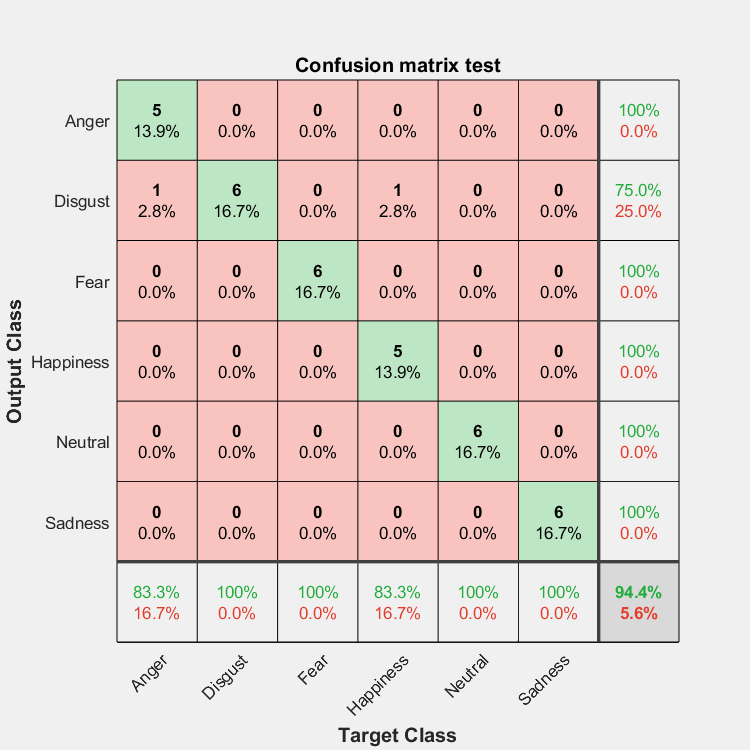

classes = categorical(table2array(data_rescaled_test(:,1)));
 % C = confusionmat(clases,yfit);
% C1 =confusionchart(C);
Order = categorical(["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]);
C2 = confusionmat(classes, categorical(yfit),'Order', Order);
figure();
% C3 = confusionchart(C2, Order);
% grid
% figure(2);
C4 = plotconfusion(classes, categorical(yfit));
title('Confusion matrix test')
grid

Compute the accuracy, precision, recall, and F-score.

D=diag(C2); L=length(C2);
accuracy_testing = sum(D)/sum(C2, "all");
%(Number of true positives + Number of true negatives)/Total number of trials

for i=1:L
   % Number of true positives / (Number of true positives + Number of false positives)
   A=C2(:,i);
   precision_testing(i,:) = D(i)/((D(i))+(sum(A(~ismember(1:end, i))))); 
   % Number of false=all items column i but the one on the diagonal
end 

for j=1:L
    % Number of true positives /(Number of true positives + Number of false negatives)
    G = C2(j,:);
    recall_testing(j,:) = D(j)/((D(j))+(sum(G(~ismember(1:end, j)))));  
end

Fscore_testing = (2.*precision_testing.*recall_testing)./(precision_testing+recall_testing);

precision_testing = reshape(precision_testing, 1, []); 
precision_testing = array2table(precision_testing,'VariableNames',...
    {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});

recall_testing = reshape(recall_testing, 1, []); 
recall_testing = array2table(recall_testing,'VariableNames',...
    {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});

Fscore_testing = reshape(Fscore_testing, 1, []); 
Fscore_testing = array2table(Fscore_testing,'VariableNames',...
    {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});

### Optimization algorithms to choose hyperparameters

Read the data 

clc; clear; close all; 
data_ori = readtable('Database_classification_TV.xlsx');

Differences in the scales accross features may lower the accuracy and efficiency of the classifier. Particularly, wide-spread variables (e.g., spread across hundreds or thousand of units, compared to narrow-spread features across decimals or ratio of units) would trigger erroneously high weighted values, resulting in unstable data modelling.

Here, every feature (i.e., columns 2 to 31) is rescaled between 0 and 1 to ensure scale consistency for a more robust posterior classification.

Min-max normalization is used, which, contrary to standardization, does not require the data to be normally distributed. To rescale between 0 and 1, it is defined by: `(sample_column_n-minimum_of_column_n)/(maximum_of_column_n-minimum_of_column_n)`, applied to every feature.

**Minimum and maximum values will be recorded to normalize the testing data afterwards.**

minimum_values = min(table2array(data_ori(:,3:end)));
maximum_values = max(table2array(data_ori(:,3:end))); 

data_rescaled = ((table2array(data_ori(:,3:end)))-(repmat(minimum_values,...
    size(table2array(data_ori(:,3:end)),1), 1))).*repmat((maximum_values-...
    minimum_values).^(-1), size(table2array(data_ori(:,3:end)),1), 1);

data_rescaled = array2table(data_rescaled,...
    'VariableNames',{'Rate','Mean pitch(Hz)','SD pitch',...
    'Jitter local', 'Jitter ppq5','Shimmer local','Shimmer rapq5',...
    'Mean HNR (dB)','Mean intensity (dB)', 'SD intensity',...
    'F1(Hz)','F2 (Hz)','F3(Hz)','B1 in center (Hz)', 'B2 in center(Hz)'...
    'B3 in center(Hz)', 'RMS_Energy', 'Coeff1', 'Coeff2','Coeff3', 'Coeff4'...
    'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8','Coeff9', 'Coeff10', 'Coeff11'...
    'Coeff12', 'Coeff13'});

% Add the classes again
emotions = ["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]; 
emotions = repmat(emotions,(size(data_rescaled,1)/size(emotions,1)),1);    
data_rescaled = [table(emotions, 'VariableNames', {'Emotion'})  data_rescaled]; 

Construct and train the model. The basis of the code is built through the classification learner application (i.e., creation of a function based on model). However, in-hand modifications have been made.

PCA_input = {'No'}; KFolds_all = {10}; Stratify = {1}; % Adjust accordingly
Optimization = {'bayesopt', 'gridsearch', 'randomsearch'}; 

data_rescaled: A table containing predictors and response.

PCA_input: must be 'No' or the percentage of the desired explained variance.

Multiclass: only for data with more than 2 classes: binary SVM to determine pairs of classes (onevsone) or to distinguish every class from the others (onevsall). Must be: 'onevsone' or 'onevsall'.

Kernel: must be 'quadratic', 'linear', 'gaussian' or 'cubic'

KernelScale: scaling for the data before applying the kernel. Must be a number between 0.001 and 1000, or 'auto'. If is a number, the algorithm divides all elements of the predictor matrix by the value secified. If set to 'auto' the algotithm selects an appropriate scale factor using a heuristic procedure. This heuristic procedure uses subsampling, so estimates can vary from one call to another. see: [https://www.mathworks.com/help/stats/fitrsvm.html#busljl4_sep_shared-KernelScale](https://www.mathworks.com/help/stats/fitrsvm.html#busljl4_sep_shared-KernelScale)

BoxConstraint: must be a number between 0.001 and 1000. Controls the maximum penalty imposed on  margin-violating observations and helps to prevent overfitting. Fewer support vectors with increasing the box constraint, but increasing computation time. see: [https://www.mathworks.com/help/stats/fitcsvm.html#bt8v_z4-1](https://www.mathworks.com/help/stats/fitcsvm.html#bt8v_z4-1)

KFolds: number of folds for cross-validation. Must be a number or 'Leaveout' for leave-one-out cross-validation.

Stratify: must be 1 for 'true' or 0 for 'false'. If true each group will contain an equal number of samples per class. If false, a nonstratified random partition is applied during cross-validation

Output variables of interest: trainedClassifier: A struct containing the trained classifier. The struct contains various fields with information about the trained classifier.

trainedClassifier.predictFcn: A function to make predictions on new data. 

accuracy_validation: A double containing the overally accuracy.

recall_validation: A table containing recall values

precision_validation:  A table containing precision values

Fscore_validation:  A table containing Fscore values

**Run the algorithm with several options of hyperparameters' optimizations methods and store the data in cell. Hyperparameters that leads to the best results (accuracy, Fscore, precision and recall) should be kept.**

ans = 'PCA option = No'

ans = 'KFolds option = 10'

ans = 'Stratify option = 1'

ans = 'Optimization option = bayesopt'

|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale | KernelFuncti-| PolynomialOr-|  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | on           | der          |              |
|=================================================================================================================================================================|
|    1 | Best   |     0.19444 |      29.699 |     0.19444 |     0.19444 |     onevsall |        696.6 |            - |       linear |            - |         true |
|    2 | Accept |     0.20635 |      1.1806 |     0.19444 |      0.2004 |     onevsall |       591.76 |            - |   polynomial |            2 |         true |
|    3 | Best   

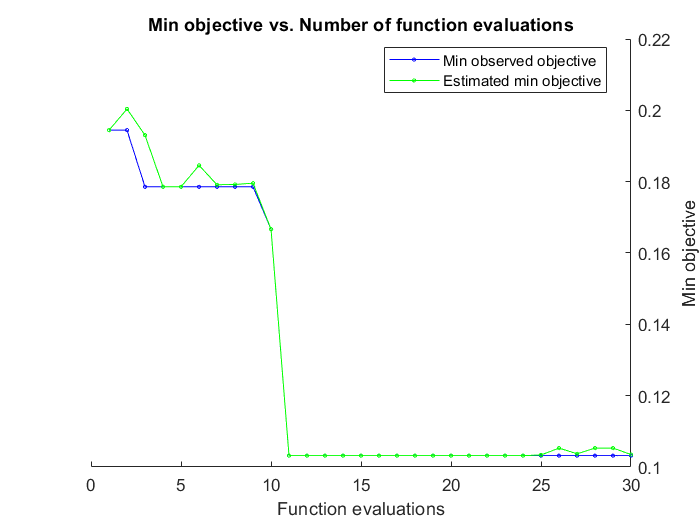


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 167.7672 seconds
Total objective function evaluation time: 146.1292

Best observed feasible point:
     Coding     BoxConstraint    KernelScale    KernelFunction    PolynomialOrder    Standardize
    ________    _____________    ___________    ______________    _______________    ___________

    onevsone      0.0010403          NaN          polynomial             4              false   

Observed objective function value = 0.10317
Estimated objective function value = 0.1035
Function evaluation time = 1.9851

Best estimated feasible point (according to models):
     Coding     BoxConstraint

ans = 'Optimization option = gridsearch'

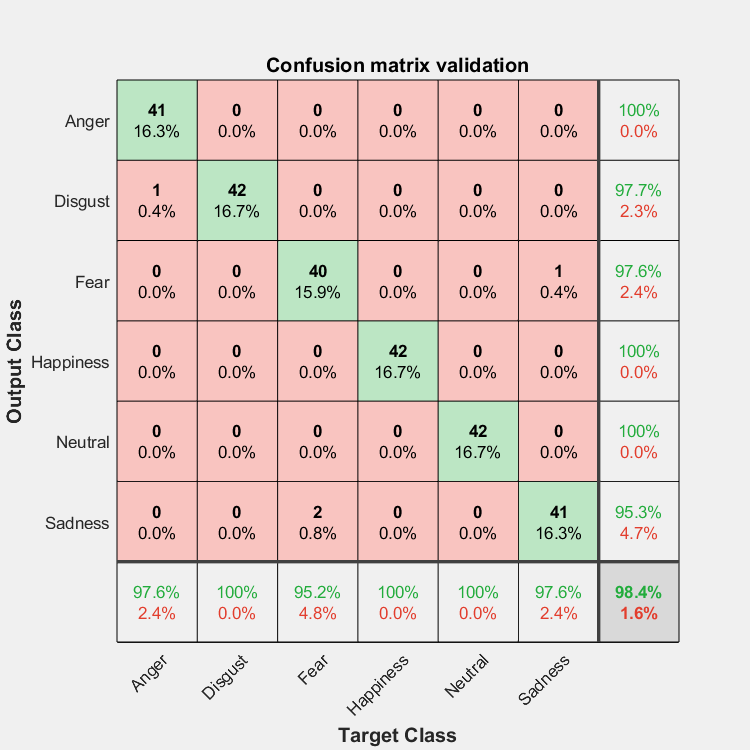

|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale | KernelFuncti-| PolynomialOr-|  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | on           | der          |              |
|=================================================================================================================================================================|
|    1 | Best   |     0.31349 |      0.5515 |     0.31349 |     0.31349 |     onevsall |    0.0088159 |       2.0085 |     gaussian |            - |         true |
|    2 | Best   |     0.11905 |     0.67073 |     0.11905 |     0.12678 |     onevsone |        68.44 |            - |       linear |            - |        false |
|    3 | Accept 

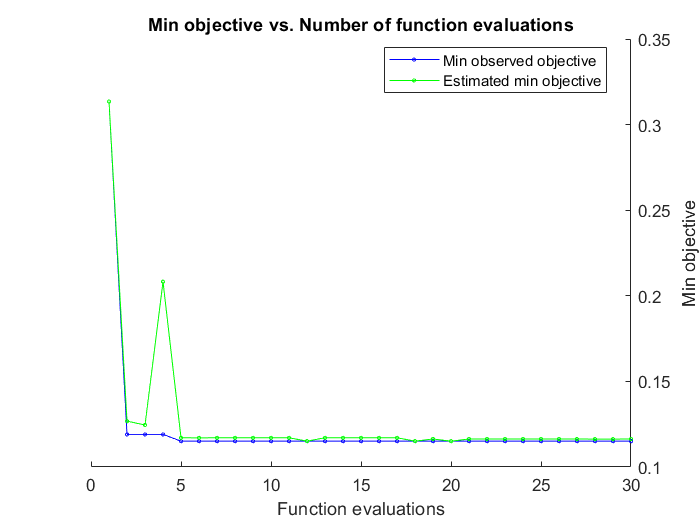


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 33.1284 seconds
Total objective function evaluation time: 21.3147

Best observed feasible point:
     Coding     BoxConstraint    KernelScale    KernelFunction    PolynomialOrder    Standardize
    ________    _____________    ___________    ______________    _______________    ___________

    onevsone       35.638            NaN            linear              NaN             false   

Observed objective function value = 0.11508
Estimated objective function value = 0.11634
Function evaluation time = 0.65144

Best estimated feasible point (according to models):
     Coding     BoxConstraint

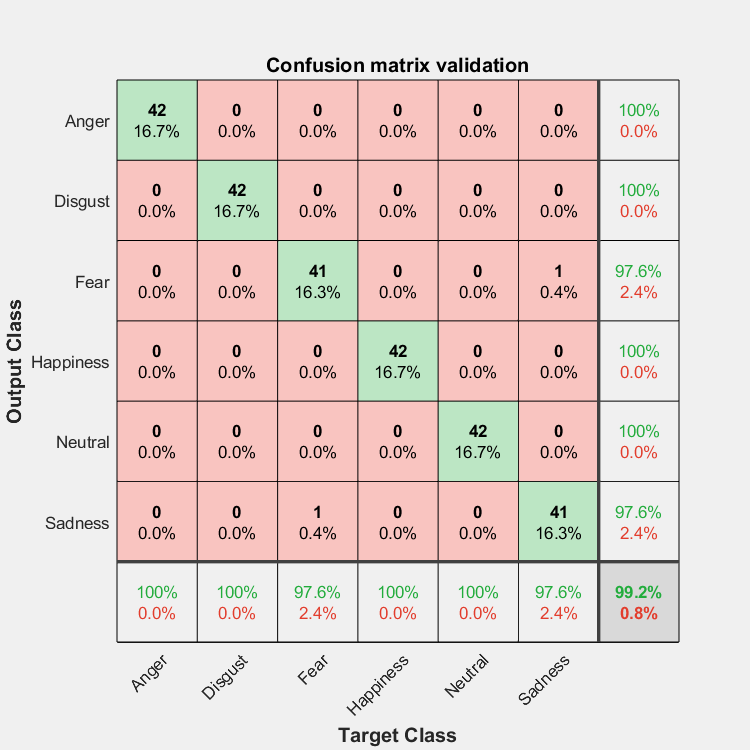

ans = 'Optimization option = randomsearch'

|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale | KernelFuncti-| PolynomialOr-|  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | on           | der          |              |
|=================================================================================================================================================================|
|    1 | Best   |     0.11905 |      1.4681 |     0.11905 |     0.11905 |     onevsone |       3.4512 |            - |       linear |            - |        false |
|    2 | Accept |     0.24206 |     0.43081 |     0.11905 |     0.12394 |     onevsall |      0.20863 |       361.21 |     gaussian |            - |         true |
|    3 | Accept 

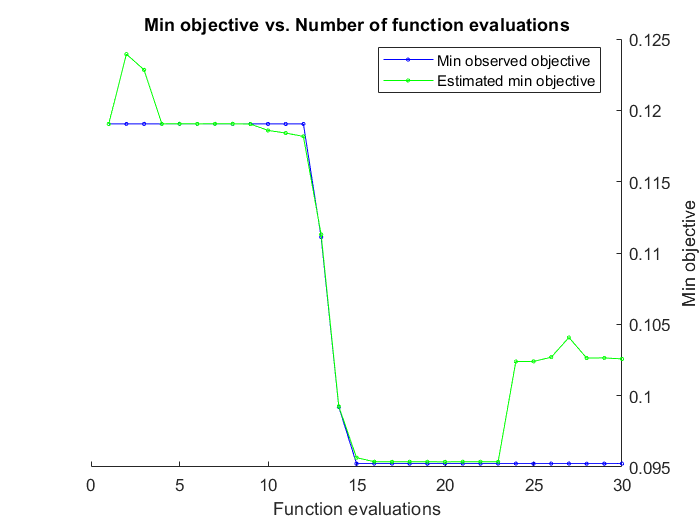


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 122.6453 seconds
Total objective function evaluation time: 112.6603

Best observed feasible point:
     Coding     BoxConstraint    KernelScale    KernelFunction    PolynomialOrder    Standardize
    ________    _____________    ___________    ______________    _______________    ___________

    onevsone       38.385            NaN            linear              NaN             false   

Observed objective function value = 0.095238
Estimated objective function value = 0.10361
Function evaluation time = 0.6945

Best estimated feasible point (according to models):
     Coding     BoxConstrai

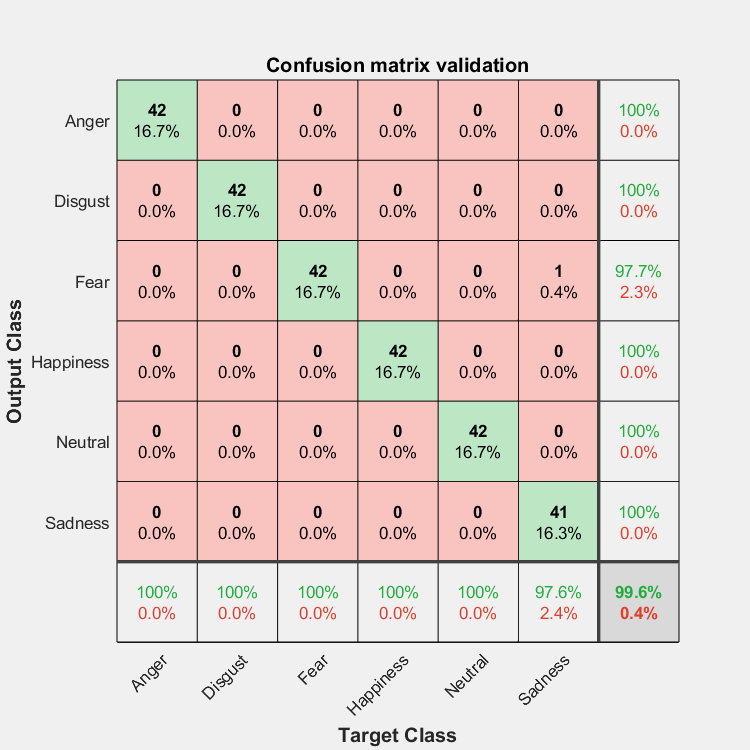

predictorNames = {'Rate', 'Mean pitch(Hz)', 'SD pitch', 'Jitter local', 'Jitter ppq5', 'Shimmer local', 'Shimmer rapq5', 'Mean HNR (dB)', 'Mean intensity (dB)', 'SD intensity', 'F1(Hz)', 'F2 (Hz)', 'F3(Hz)', 'B1 in center (Hz)', 'B2 in center(Hz)', 'B3 in center(Hz)', 'RMS_Energy', 'Coeff1', 'Coeff2', 'Coeff3', 'Coeff4', 'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8', 'Coeff9', 'Coeff10', 'Coeff11', 'Coeff12', 'Coeff13'};
predictors = data_rescaled(:, predictorNames);
response = data_rescaled.Emotion;
% classes_nb = groupsummary(data_rescaled(:,1),"Emotion");
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];

for PCA_options = 1:1:size(PCA_input,2) %for every value of PCA_input
    ['PCA option = ' num2str(PCA_input{1,PCA_options})]
    for KFolds_options = 1:1:size(KFolds_all,2) %for every value of KFolds
    ['KFolds option = ' num2str(KFolds_all{1,KFolds_options})]
        for Stratify_options = 1:1:size(Stratify,2) %for every value of Stratify
        ['Stratify option = ' num2str(Stratify{1,Stratify_options})]
            for Optimization_options = 1:1:size(Optimization,2) %for every value of Stratify
            ['Optimization option = ' num2str(Optimization{1,Optimization_options})]
            
            if isa(PCA_input{1,PCA_options},'double')
                PCA_decision = double(isa(PCA_input{1,PCA_options},'double'));
             else
                PCA_decision = PCA_input{1,PCA_options};
             end
    
             switch PCA_decision
                case 1
                    % Apply a PCA to the predictor matrix.
                    % Run PCA on numeric predictors only. Categorical predictors are passed through PCA untouched.
                    isCategoricalPredictorBeforePCA = isCategoricalPredictor;
                    numericPredictors = predictors(:, ~isCategoricalPredictor);
                    numericPredictors = table2array(varfun(@double, numericPredictors));
                    % 'inf' values have to be treated as missing data for PCA.
                    numericPredictors(isinf(numericPredictors)) = NaN;
                    [pcaCoefficients, pcaScores, ~, ~, explained, pcaCenters] = pca(...
                        numericPredictors);
                    % Keep enough components to explain the desired amount of variance.
                    explainedVarianceToKeepAsFraction = 95/100;
                    numComponentsToKeep = find(cumsum(explained)/sum(explained) >= explainedVarianceToKeepAsFraction, 1);
                    pcaCoefficients = pcaCoefficients(:,1:numComponentsToKeep);
                    predictors = [array2table(pcaScores(:,1:numComponentsToKeep)), predictors(:, isCategoricalPredictor)];
                    isCategoricalPredictor = [false(1,numComponentsToKeep), true(1,sum(isCategoricalPredictor))];
            
                    % Perform cross-validation
                    KFolds = KFolds_all{1, KFolds_options};
                    KFolds_decision = double(isa(KFolds,'double'));
                    switch KFolds_decision
                        case 1
                            cvp = cvpartition(response, "KFold", KFolds, "Stratify",logical(Stratify{1,Stratify_options}));
            %                 Plot number of samples in folds
                            numClasses = size(groupsummary(data_rescaled(:,1),"Emotion"),1);
                            nTestData = zeros(KFolds,numClasses); figure()
                            for i = 1:KFolds
                                testClasses = response(cvp.test(i));
                                nCounts = countcats(categorical(testClasses));
                                try nTestData(i,:) = nCounts';
                                    bar(nTestData)
                                    xlabel('Test Set (Fold)'); ylabel('Number of Observations');
                                    title('Partition'); legend(categories(categorical(response)))
    %                               close all
                                catch
    %                               close all
                                end
                            end            
                        case 0
                            cvp = cvpartition(response, "Leaveout");
                    end
            
                    % Optimize hyperparameters for the svm algorithm
                    classificationSVM = fitcecoc(predictors, response, 'OptimizeHyperparameters','all',...
                            'Learners', 'svm', 'HyperparameterOptimizationOptions', struct('Optimizer', ...
                            'bayesopt', 'CVPartition', cvp));
                    % Extract best hyperparameters
                    bestHyperparameters = bestPoint(classificationSVM.HyperparameterOptimizationResults);
                    bestHyperparameters = [table(categorical(convertCharsToStrings(Optimization{1, Optimization_options})),...
                        'VariableNames', {'Optimizer'})  bestHyperparameters];
    
                     % Reminder of the structure of the model 
                    model_structure = [];
                    model_structure{PCA_options, KFolds_options, Stratify_options, Optimization_options} = ...
                        ['PCA option = ' num2str(PCA_input{1,PCA_options})...
                        ' - KFolds option = ' num2str(KFolds_all{1,KFolds_options})...
                        ' - Stratify option = ' num2str(Stratify{1,Stratify_options})...
                        ' - Optimizer = '  char(table2array(bestHyperparameters(1,1)))...
                        ' - Multiclass = '  char(table2array(bestHyperparameters(1,2)))...
                        ' - BoxConstraint = ' num2str(table2array(bestHyperparameters(1,3)))...
                        ' - Kernelscale = '  num2str(table2array(bestHyperparameters(1,4)))...
                        ' - KernelFunction = '  char(table2array(bestHyperparameters(1,5)))...
                        ' - Polynomial order = '  num2str(table2array(bestHyperparameters(1,6)))...
                        ' - Standardize = '  char(table2array(bestHyperparameters(1,7)))];
    
            
                    % Create the result struct with predict function
                    predictorExtractionFcn = @(t) t(:, predictorNames);
                    pcaTransformationFcn = @(x) [ array2table((table2array(varfun(@double, x(:, ~isCategoricalPredictorBeforePCA))) - pcaCenters) * pcaCoefficients), x(:,isCategoricalPredictorBeforePCA) ];
                    svmPredictFcn = @(x) predict(classificationSVM, x);
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.predictFcn = @(x) svmPredictFcn(pcaTransformationFcn(predictorExtractionFcn(x)));
                    
                    % Add additional fields to the result struct
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.RequiredVariables = {'B1 in center (Hz)', 'B2 in center(Hz)', 'B3 in center(Hz)', 'Coeff1', 'Coeff10', 'Coeff11', 'Coeff12', 'Coeff13', 'Coeff2', 'Coeff3', 'Coeff4', 'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8', 'Coeff9', 'F1(Hz)', 'F2 (Hz)', 'F3(Hz)', 'Jitter local', 'Jitter ppq5', 'Mean HNR (dB)', 'Mean intensity (dB)', 'Mean pitch(Hz)', 'RMS_Energy', 'Rate', 'SD intensity', 'SD pitch', 'Shimmer local', 'Shimmer rapq5'};
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.PCACenters = pcaCenters;
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.PCACoefficients = pcaCoefficients;
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.ClassificationSVM = classificationSVM;
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.About = 'This struct is a trained model exported from Classification Learner R2022a.';
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
             
                    % Compute validation accuracy
                    validationPredictions = resubPredict(classificationSVM);
                    correctPredictions = strcmp(strtrim(validationPredictions), strtrim(response));
                    isMissing = cellfun(@(x) all(isspace(x)), response, 'UniformOutput', true);
                    correctPredictions = correctPredictions(~isMissing);
                    accuracy_validation{PCA_options, KFolds_options, Stratify_options, Optimization_options} = sum(correctPredictions)/length(correctPredictions);
            
                    %  Compute the confusion matrix during validation 
                    classes = categorical(response);
                    Order = categorical(["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]);
                    C2 = confusionmat(classes, categorical(validationPredictions),'Order', Order);
                    figure();
                    C4 = plotconfusion(classes, categorical(validationPredictions));
                    title('Confusion matrix validation')
                    grid
            
            %         Compute precision, recall and Fscore during validation
                    D=diag(C2); L=length(C2); precision_validation = [];       
                    for i=1:L
                       % Number of true positives / (Number of true positives + Number of false positives)
                       A=C2(:,i);
                       precision_validation(i,:) = D(i)/((D(i))+(sum(A(~ismember(1:end, i))))); 
                       % Number of false=all items column i but the one on the diagonal
                    end 
                    recall_validation = [];
                    for j=1:L
                        % Number of true positives /(Number of true positives + Number of false negatives)
                        G = C2(j,:);
                        recall_validation(j,:) = D(j)/((D(j))+(sum(G(~ismember(1:end, j)))));  
                    end
                    Fscore_validation = [];
                    Fscore_validation = (2.*precision_validation.*recall_validation)./(precision_validation+recall_validation);
                    
                    precision_validation = reshape(precision_validation, 1, []); 
                    precision_validation_tot{PCA_options, KFolds_options, Stratify_options, Optimization_options} = array2table(precision_validation,'VariableNames',...
                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                    
                    recall_validation = reshape(recall_validation, 1, []); 
                    recall_validation_tot{PCA_options, KFolds_options, Stratify_options, Optimization_options} = array2table(recall_validation,'VariableNames',...
                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                    
                    Fscore_validation = reshape(Fscore_validation, 1, []); 
                    Fscore_validation_tot{PCA_options, KFolds_options, Stratify_options, Optimization_options} = array2table(Fscore_validation,'VariableNames',...
                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
            
                case 'No'
                    % Train a classifier
                    % Perform cross-validation
                    KFolds = KFolds_all{1, KFolds_options};
                    KFolds_decision = double(isa(KFolds,'double'));
                    switch KFolds_decision
                        case 1
                            cvp = cvpartition(response, "KFold", KFolds, "Stratify",logical(Stratify{1,Stratify_options}));
            %                 Plot number of samples in folds
                            numClasses = size(groupsummary(data_rescaled(:,1),"Emotion"),1);
                            nTestData = zeros(KFolds,numClasses);figure();
                            for i = 1:KFolds
                                testClasses = response(cvp.test(i));
                                nCounts = countcats(categorical(testClasses));
                                try nTestData(i,:) = nCounts';
                                    bar(nTestData)
                                    xlabel('Test Set (Fold)'); ylabel('Number of Observations');
                                    title('Partition'); legend(categories(categorical(response)))
%                                   close all
                                catch
%                                  close all
                                 end
                            end
            
                        case 0
                            cvp = cvpartition(response, "Leaveout");
                    end
            
                    % Optimize hyperparameters for the svm algorithm
                    classificationSVM = fitcecoc(predictors, response, 'OptimizeHyperparameters','all',...
                            'Learners', 'svm', 'HyperparameterOptimizationOptions', struct('Optimizer', ...
                            'bayesopt', 'CVPartition', cvp));
                    % Extract best hyperparameters
                    bestHyperparameters = bestPoint(classificationSVM.HyperparameterOptimizationResults);
                    bestHyperparameters = [table(categorical(convertCharsToStrings(Optimization{1, Optimization_options})),...
                        'VariableNames', {'Optimizer'})  bestHyperparameters];
    
                     % Reminder of the structure of the model 
                    model_structure = [];
                    model_structure{PCA_options, KFolds_options, Stratify_options, Optimization_options} = ...
                        ['PCA option = ' num2str(PCA_input{1,PCA_options})...
                        ' - KFolds option = ' num2str(KFolds_all{1,KFolds_options})...
                        ' - Stratify option = ' num2str(Stratify{1,Stratify_options})...
                        ' - Optimizer = '  char(table2array(bestHyperparameters(1,1)))...
                        ' - Multiclass = '  char(table2array(bestHyperparameters(1,2)))...
                        ' - BoxConstraint = ' num2str(table2array(bestHyperparameters(1,3)))...
                        ' - Kernelscale = '  num2str(table2array(bestHyperparameters(1,4)))...
                        ' - KernelFunction = '  char(table2array(bestHyperparameters(1,5)))...
                        ' - Polynomial order = '  num2str(table2array(bestHyperparameters(1,6)))...
                        ' - Standardize = '  char(table2array(bestHyperparameters(1,7)))];

                    % Create the result struct with predict function
                    predictorExtractionFcn = @(t) t(:, predictorNames);
                    svmPredictFcn = @(x) predict(classificationSVM, x);
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));
                    
                    % Add additional fields to the result struct
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.RequiredVariables = {'B1 in center (Hz)', 'B2 in center(Hz)', 'B3 in center(Hz)', 'Coeff1', 'Coeff10', 'Coeff11', 'Coeff12', 'Coeff13', 'Coeff2', 'Coeff3', 'Coeff4', 'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8', 'Coeff9', 'F1(Hz)', 'F2 (Hz)', 'F3(Hz)', 'Jitter local', 'Jitter ppq5', 'Mean HNR (dB)', 'Mean intensity (dB)', 'Mean pitch(Hz)', 'RMS_Energy', 'Rate', 'SD intensity', 'SD pitch', 'Shimmer local', 'Shimmer rapq5'};
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.ClassificationSVM = classificationSVM;
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.About = 'This struct is a trained model exported from Classification Learner R2022a.';
                    trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
            
                    % Compute validation accuracy
                    validationPredictions = resubPredict(classificationSVM);
                    correctPredictions = strcmp(strtrim(validationPredictions), strtrim(response));
                    isMissing = cellfun(@(x) all(isspace(x)), response, 'UniformOutput', true);
                    correctPredictions = correctPredictions(~isMissing);
                    accuracy_validation{PCA_options, KFolds_options, Stratify_options, Optimization_options} = sum(correctPredictions)/length(correctPredictions);
                    
            %       Compute the confusion matrix during validation 
                    classes = categorical(response);
                    Order = categorical(["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]);
                    C2 = confusionmat(classes, categorical(validationPredictions),'Order', Order);
                    figure();
                    C4 = plotconfusion(classes, categorical(validationPredictions));
                    title('Confusion matrix validation')
                    grid
            
            %         Compute precision, recall and Fscore during validation
                    D=diag(C2); L=length(C2); precision_validation = [];        
                    for i=1:L
                       % Number of true positives / (Number of true positives + Number of false positives)
                       A=C2(:,i);
                       precision_validation(i,:) = D(i)/((D(i))+(sum(A(~ismember(1:end, i))))); 
                       % Number of false=all items column i but the one on the diagonal
                    end 
                    recall_validation = [];
                    for j=1:L
                        % Number of true positives /(Number of true positives + Number of false negatives)
                        G = C2(j,:);
                        recall_validation(j,:) = D(j)/((D(j))+(sum(G(~ismember(1:end, j)))));  
                    end
                    Fscore_validation = [];
                    Fscore_validation = (2.*precision_validation.*recall_validation)./(precision_validation+recall_validation);
                    
                    precision_validation = reshape(precision_validation, 1, []); 
                    precision_validation_tot{PCA_options, KFolds_options, Stratify_options, Optimization_options} = array2table(precision_validation,'VariableNames',...
                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                    
                    recall_validation = reshape(recall_validation, 1, []); 
                    recall_validation_tot{PCA_options, KFolds_options, Stratify_options, Optimization_options} = array2table(recall_validation,'VariableNames',...
                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
                    
                    Fscore_validation = reshape(Fscore_validation, 1, []); 
                    Fscore_validation_tot{PCA_options, KFolds_options, Stratify_options, Optimization_options} = array2table(Fscore_validation,'VariableNames',...
                        {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});
            
             end
           end
        end
    end
end            

Read testing data 

data_test = readtable('Database_classification_Test.xlsx');

data_rescaled_test = ((table2array(data_test(:,3:end)))-(repmat(minimum_values,...
    size(table2array(data_test(:,3:end)),1), 1))).*repmat((maximum_values-...
    minimum_values).^(-1), size(table2array(data_test(:,3:end)),1), 1);

data_rescaled_test = array2table(data_rescaled_test,...
    'VariableNames',{'Rate','Mean pitch(Hz)','SD pitch',...
    'Jitter local', 'Jitter ppq5','Shimmer local','Shimmer rapq5',...
    'Mean HNR (dB)','Mean intensity (dB)', 'SD intensity',...
    'F1(Hz)','F2 (Hz)','F3(Hz)','B1 in center (Hz)', 'B2 in center(Hz)'...
    'B3 in center(Hz)', 'RMS_Energy', 'Coeff1', 'Coeff2','Coeff3', 'Coeff4'...
    'Coeff5', 'Coeff6', 'Coeff7', 'Coeff8','Coeff9', 'Coeff10', 'Coeff11'...
    'Coeff12', 'Coeff13'});

% Add the classes again
emotions = ["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]; 
emotions = repmat(emotions,(size(data_rescaled_test,1)/size(emotions,1)),1);    
data_rescaled_test = [table(emotions, 'VariableNames', {'Emotion'})  data_rescaled_test]; 

Use the trained model to make predictions on the test data.

% Asjust to best hyperparameters according to your criterion (e.g., best accuracy or best Fscore)
PCA_options = 1;
KFolds_options =1;
Stratify_options =1;
Optimization_options = 1;

yfit = trainedClassifier{PCA_options, KFolds_options, Stratify_options, Optimization_options}.predictFcn(data_rescaled_test);

Compute the confusion matrix

classes = categorical(table2array(data_rescaled_test(:,1)));
 % C = confusionmat(clases,yfit);
% C1 =confusionchart(C);
Order = categorical(["Anger";"Disgust";"Fear";"Happiness";"Neutral";"Sadness"]);
C2 = confusionmat(classes, categorical(yfit),'Order', Order);
figure();
% C3 = confusionchart(C2, Order);
% grid
% figure(2);
C4 = plotconfusion(classes, categorical(yfit));
title('Confusion matrix test')
grid

Compute the accuracy, precision, recall, and F-score.

D=diag(C2); L=length(C2);
accuracy_testing = sum(D)/sum(C2, "all");
%(Number of true positives + Number of true negatives)/Total number of trials

for i=1:L
   % Number of true positives / (Number of true positives + Number of false positives)
   A=C2(:,i);
   precision_testing(i,:) = D(i)/((D(i))+(sum(A(~ismember(1:end, i))))); 
   % Number of false=all items column i but the one on the diagonal
end 

for j=1:L
    % Number of true positives /(Number of true positives + Number of false negatives)
    G = C2(j,:);
    recall_testing(j,:) = D(j)/((D(j))+(sum(G(~ismember(1:end, j)))));  
end

Fscore_testing = (2.*precision_testing.*recall_testing)./(precision_testing+recall_testing);

precision_testing = reshape(precision_testing, 1, []); 
precision_testing = array2table(precision_testing,'VariableNames',...
    {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});

recall_testing = reshape(recall_testing, 1, []); 
recall_testing = array2table(recall_testing,'VariableNames',...
    {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});

Fscore_testing = reshape(Fscore_testing, 1, []); 
Fscore_testing = array2table(Fscore_testing,'VariableNames',...
    {'Anger','Disgust','Fear','Happiness','Neutral','Sadness'});